Ripley dataset

load breast.mat

Xtrain = trainset;
Ytrain = labels_train;

Xtest = testset;
Ytest = labels_test;

Visualize the data. Inspect the data structure: what seems to be important prop-

erties of the data?

30 inputs , binary classification 

 Which classi�cation model do you think you need, based on the

complexity of the data?

linear, RBF 

## Visualize the training data

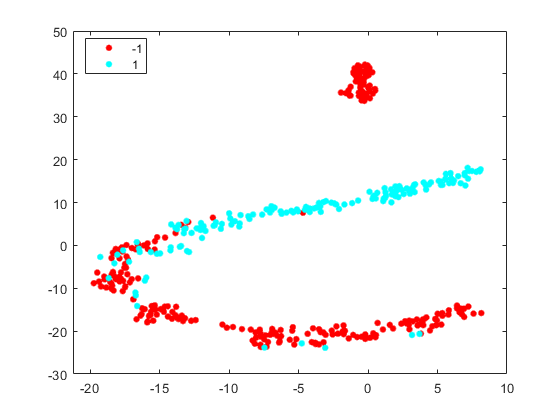

rng default % for reproducibility
Y = tsne(Xtrain,'Algorithm','barneshut','NumPCAComponents',2);

figure 
gscatter(Y(:,1),Y(:,2),Ytrain)

## Visualize the test data

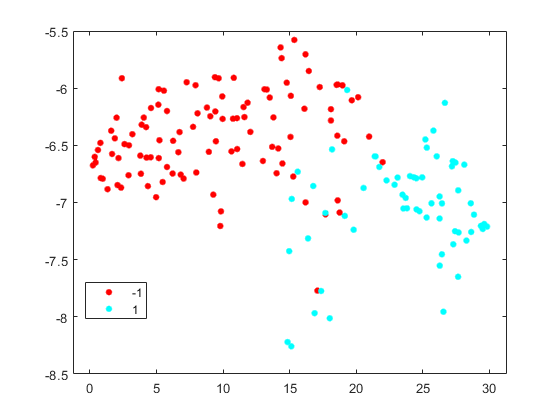

rng default % for reproducibility
Y = tsne(Xtest,'Algorithm','barneshut','NumPCAComponents',2);

figure 
gscatter(Y(:,1),Y(:,2),Ytest)

## Linear model

Try out different models (linear, polynomial, RBF kernel) with tuned hyperparameter

and kernel parameters. Compute the ROC curves. Which model performs best?

Which model would you choose?

Define the model parameters

type = 'c';
kernel_type = 'lin_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

gam = tunelssvm(model,'simplex','leaveoneoutlssvm', {'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.068922
                                          F(X)=         0.0325
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  leaveoneoutlssvm
    kernel function                 lin_kernel
 

 3. starting value:                   0.068922

 Iteration   Func-count    min f(x)    log(gamma)      Procedure

     1           2     3.250000e-02     -2.6748           initial 
     2           4     3.250000e-02     -2.6748           contract inside 
     3           6     3.250000e-02     -2.6748           contract inside 
optimisation terminated sucessfully (TolFun criterion)

Simplex results: 
X=0.068922  , F(X)=3.250000e-02 

Obtained hyper-parameters: [gamma]: 0.068922


Compute the ROC curves

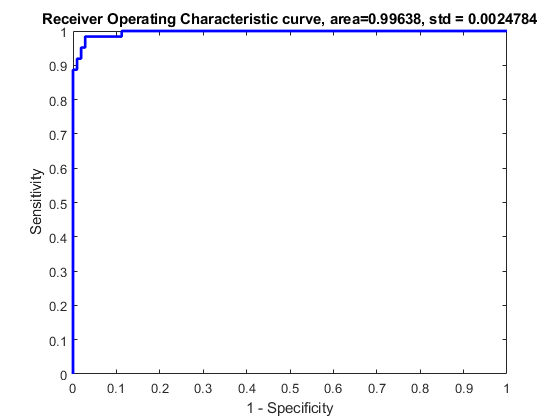

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, [],'lin_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, [],'lin_kernel'},{alpha, b},Xtest);
figure Name 'ROC Linear Kernel'
roc(Ylatent, Ytest);

## Polynomial model

Define the model parameters

type = 'c';
kernel_type = 'poly_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

[gam,sig2] = tunelssvm(model,'simplex','crossvalidatelssvm', {10, 'misclass'});


   Determine initial hyperparameters for simplex...
  |-                                              -|
  **************************************************

 1. Simulated Annealing results:          [gam]         0.01434
                                          [t]           6.7141
                                          [degree]      3
                                          F(X)=         0.095
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 poly_kernel
 

 3. starting values:                   0.01434      6.7141           3

 Iteration   Func-count    min f(x)    log(gamma)      log(t)        Procedure

     1           3     9.500000e-02     -4.2447         1.9042         initial   
     2           5     6.750000e-02     -6.6447         3.7042         expand   
     3           7     4.000000e-02     -7.8447         2.2042         expand   
     4    

Compute the ROC curves

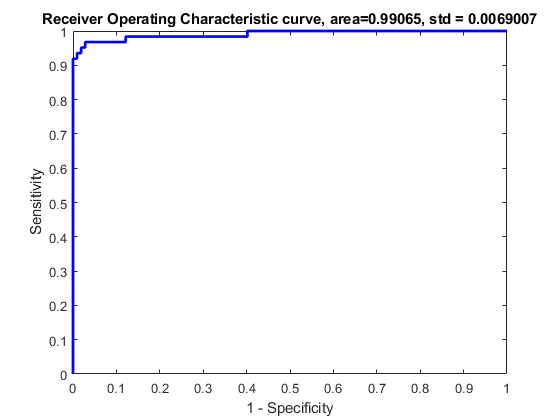

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'poly_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'poly_kernel'},{alpha, b},Xtest);
figure Name 'ROC Poly Kernel'
roc(Ylatent, Ytest);

## RBF model

Define the model parameters

type = 'c';
kernel_type = 'RBF_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


Tuning the parameter

[gam,sig2] = tunelssvm(model,'simplex','crossvalidatelssvm', {10, 'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         42.3302
                                          [sig2]        45.7758
                                          F(X)=         0.0125
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   42.3302      45.7758

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.250000e-02     3.7455        3.8238      initial 
     2           7     1.250000e-02     3.7455        3.8238      shrink 
     3           9     1.250000e-02     3.7455        3.8238      contract inside 
     4          11     1.250000e-02     3.7455        3.8238    

Compute the ROC curves

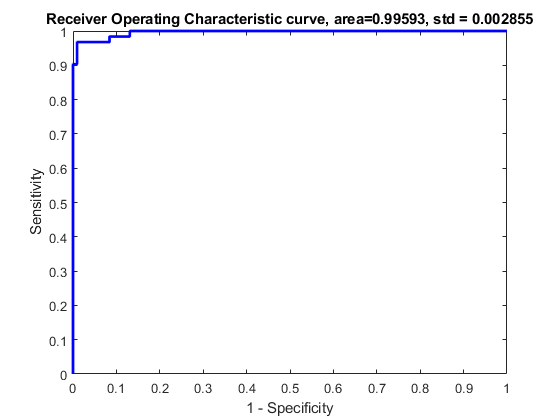

[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'});
[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'},{alpha, b},Xtest);
figure Name 'ROC Poly Kernel'
roc(Ylatent, Ytest);